Parameters and constants

p4 = 4;
p6 = 4;
p8 = 6;
a = (0.4 + 0.2*p4)/1000;          % Wire radius [m]
w = (24 + 2*p8)/1000;             % Horizontal distance between wires [m]
h1 = (12 + p6)/1000;              % Height of wire #1 [m]
h2 = (12 + p4)/1000;              % Height of wire #2 [m]
mu0 = 4*pi*1e-7; 
h = h1;                           % Both wires are at the same height
l = (450 + 20*p4)/1000;           % Length [m]
rho_l1 = 7e-9;  
rho_l2 = -7e-9; 
I1 = 3;
I2 = -3;
xmin = -w;
xmax = 2*w;
ymin = 0;
ymax = 2*w;
epsilon0 = 8.85418782e-12; 
k = 1/(2*pi*epsilon0);     

3.2.1 (a)

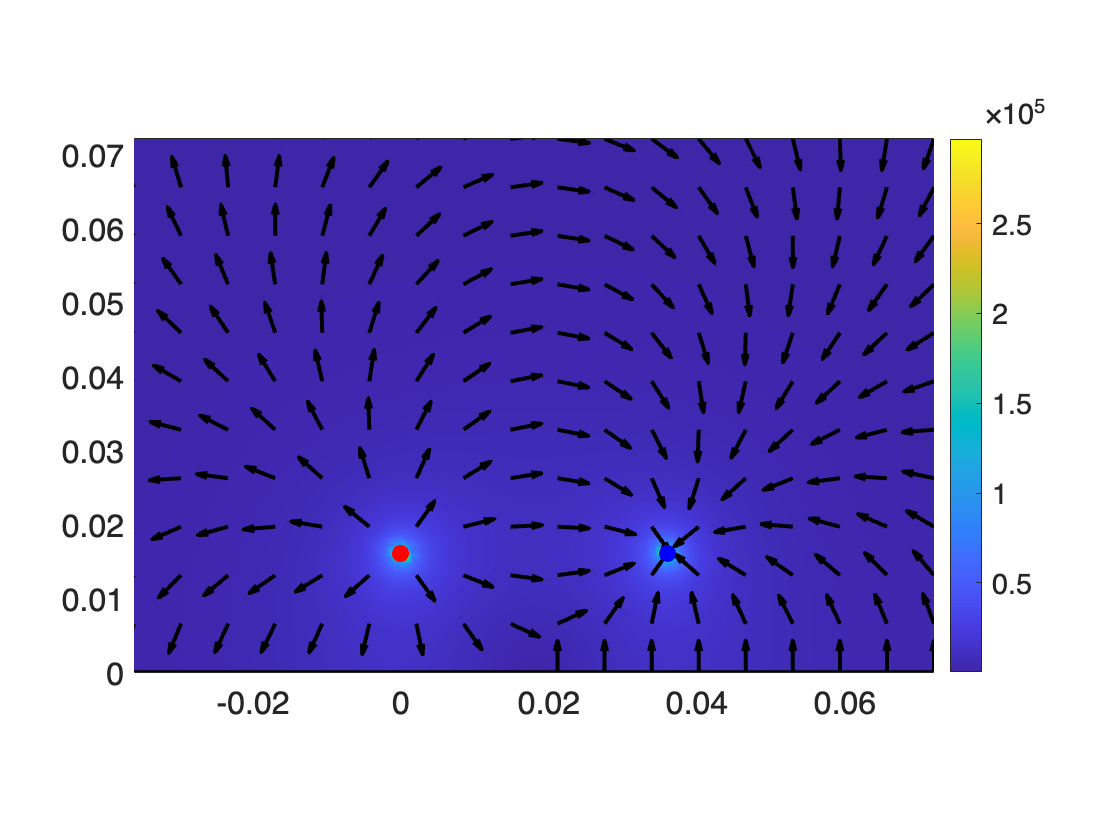

% --- Visualize scalar field ---
% Define grid points
xVtr = linspace(xmin, xmax, 90);
yVtr = linspace(ymin, ymax, 60);
[xMtx, yMtx] = meshgrid(xVtr, yVtr);

% Initialize electric field components
Ex = zeros(size(xMtx));
Ey = zeros(size(xMtx));

% Calculate electric field due to wire #1 at (0,h1) and its image at (0,-h1)
% Real wire #1
r1_squared = (xMtx).^2 + (yMtx - h1).^2;
Ex = Ex + k * rho_l1 * (xMtx) ./ r1_squared;
Ey = Ey + k * rho_l1 * (yMtx - h1) ./ r1_squared;

% Image of wire #1
r1_image_squared = (xMtx).^2 + (yMtx + h1).^2;
Ex = Ex + k * (-rho_l1) * (xMtx) ./ r1_image_squared;
Ey = Ey + k * (-rho_l1) * (yMtx + h1) ./ r1_image_squared;

% Calculate electric field due to wire #2 at (w,h2) and its image at (w,-h2)
% Real wire #2
r2_squared = (xMtx - w).^2 + (yMtx - h2).^2;
Ex = Ex + k * rho_l2 * (xMtx - w) ./ r2_squared;
Ey = Ey + k * rho_l2 * (yMtx - h2) ./ r2_squared;

% Image of wire #2
r2_image_squared = (xMtx - w).^2 + (yMtx + h2).^2;
Ex = Ex + k * (-rho_l2) * (xMtx - w) ./ r2_image_squared;
Ey = Ey + k * (-rho_l2) * (yMtx + h2) ./ r2_image_squared;

% Calculate electric field magnitude
E_magnitude = sqrt(Ex.^2 + Ey.^2);

% Concatenate scalar field (remove values that are too large)
sIdx = find(E_magnitude > 3e6); E_magnitude(sIdx) = NaN*sIdx;

% Visualize scalar field
figure(1), clf
pcolor(xMtx, yMtx, E_magnitude), hold on
shading interp
colorbar

xVtr = linspace(xmin, xmax, 18);
yVtr = linspace(ymin, ymax, 12);
[xMtx, yMtx] = meshgrid(xVtr, yVtr);

% Initialize electric field
vxFld = zeros(size(xMtx));
vyFld = zeros(size(xMtx));

small_offset = 1e-6; % Offset för att unvika zero division

% Calculate field due to wire #1 and its image
r1_squared = (xMtx).^2 + (yMtx - h1).^2 + small_offset;
vxFld = vxFld + k * rho_l1 * (xMtx) ./ r1_squared;
vyFld = vyFld + k * rho_l1 * (yMtx - h1) ./ r1_squared;

r1_image_squared = (xMtx).^2 + (yMtx + h1).^2 + small_offset;
vxFld = vxFld + k * (-rho_l1) * (xMtx) ./ r1_image_squared;
vyFld = vyFld + k * (-rho_l1) * (yMtx + h1) ./ r1_image_squared;

% Calculate field due to wire #2 and its image
r2_squared = (xMtx - w).^2 + (yMtx - h2).^2 + small_offset;
vxFld = vxFld + k * rho_l2 * (xMtx - w) ./ r2_squared;
vyFld = vyFld + k * rho_l2 * (yMtx - h2) ./ r2_squared;

r2_image_squared = (xMtx - w).^2 + (yMtx + h2).^2 + small_offset;
vxFld = vxFld + k * (-rho_l2) * (xMtx - w) ./ r2_image_squared;
vyFld = vyFld + k * (-rho_l2) * (yMtx + h2) ./ r2_image_squared;

v_magnitude = sqrt(vxFld.^2 + vyFld.^2);

vxFld_norm = vxFld ./ v_magnitude;
vyFld_norm = vyFld ./ v_magnitude;

vxFld_norm(isnan(vxFld_norm) | isinf(vxFld_norm)) = 0;
vyFld_norm(isnan(vyFld_norm) | isinf(vyFld_norm)) = 0;

% Visualize vector field with normalized vectors
figure(1)
quiver(xMtx, yMtx, vxFld_norm, vyFld_norm, 0.5, 'k', 'linewidth', 2)

% Add wire positions
plot(0, h1, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');  % Wire #1
plot(w, h2, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');  % Wire #2
plot([xmin xmax], [0 0], 'k-', 'LineWidth', 2);  % Ground plane

axis equal

set(gca, 'fontsize', 16)
axis([xmin xmax ymin ymax])

3.2.2 (b)

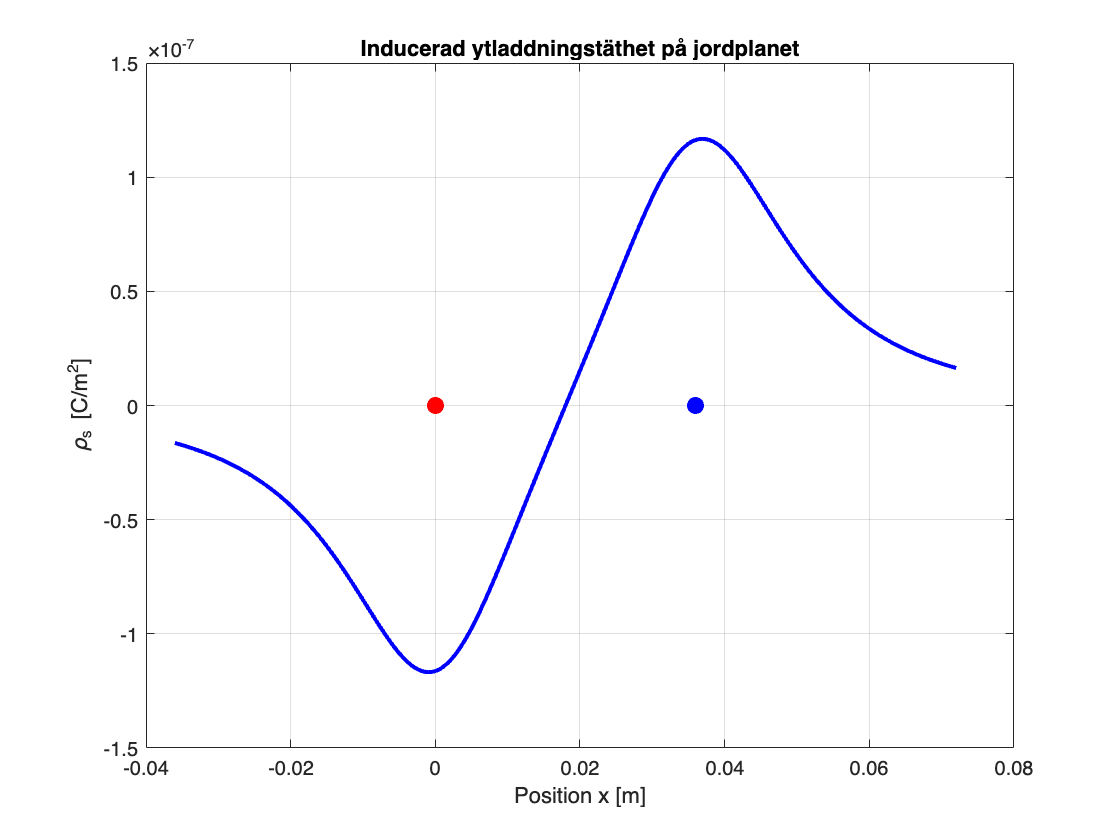

x_plot = linspace(-w, 2*w, 500);

% rho_s(x) = -(1/pi) * [ (rho_l1 * h1) / (x^2 + h1^2) + (rho_l2 * h2) / ((x-w)^2 + h2^2) ]
term1 = (rho_l1 * h1) ./ (x_plot.^2 + h1^2);
term2 = (rho_l2 * h2) ./ ((x_plot - w).^2 + h2^2);
rho_s = -(1/pi) * (term1 + term2);

figure(); 

plot(x_plot, rho_s, 'b-', 'LineWidth', 2);
hold on; 

plot(0, 0, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); 
plot(w, 0, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); 

title('Inducerad ytladdningstäthet på jordplanet');
xlabel('Position x [m]');
ylabel('\rho_s [C/m^2]');
grid on; 

hold off;

3.2.3 (a)

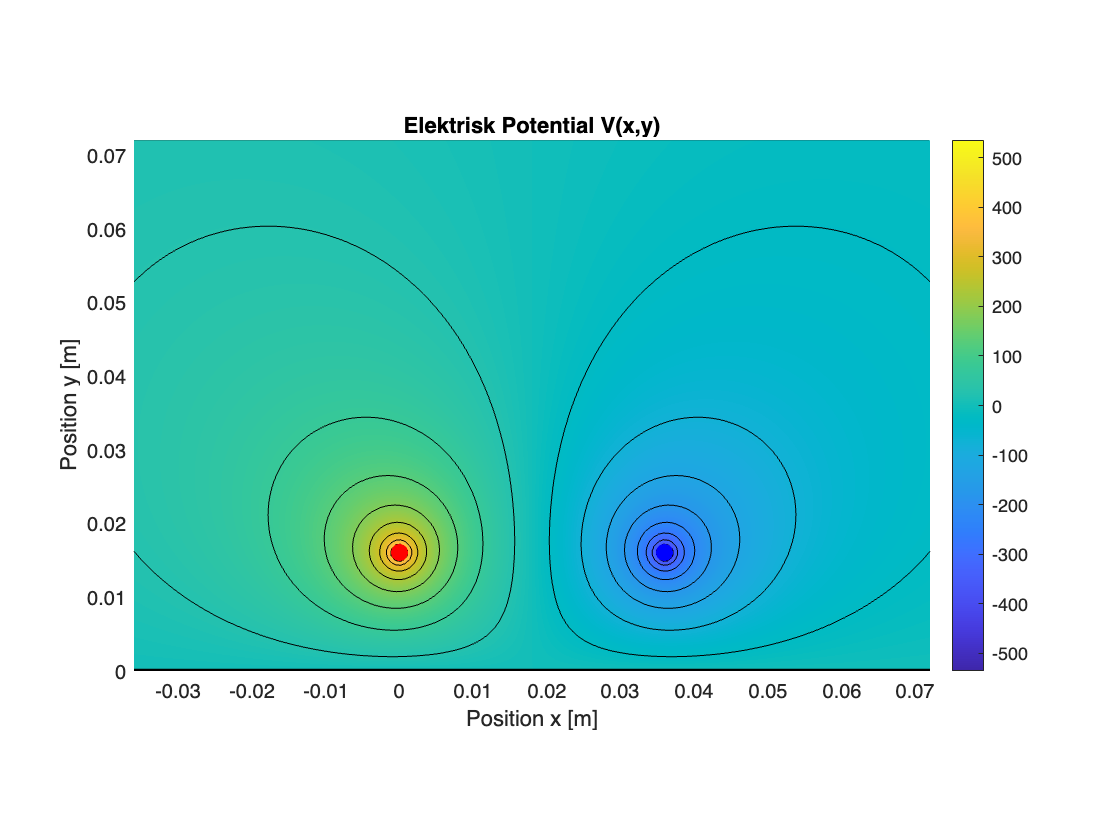

xVtr = linspace(xmin, xmax, 180); 
yVtr = linspace(ymin, ymax, 120);
[xMtx, yMtx] = meshgrid(xVtr, yVtr);

% V(x,y) = (k/2)*rho_l1*log( (x^2+(y+h1)^2) / (x^2+(y-h1)^2) ) + ...
%          (k/2)*rho_l2*log( ((x-w)^2+(y+h2)^2) / ((x-w)^2+(y-h2)^2) )

r1_sq = xMtx.^2 + (yMtx - h1).^2;
r1prime_sq = xMtx.^2 + (yMtx + h1).^2;
r2_sq = (xMtx - w).^2 + (yMtx - h2).^2;
r2prime_sq = (xMtx - w).^2 + (yMtx + h2).^2;

small_offset = 1e-12; % Offset för undvika zero division
r1_sq = r1_sq + small_offset;
r2_sq = r2_sq + small_offset;

% Beräkna termerna i V
term1_V = (k/2) * rho_l1 * log(r1prime_sq ./ r1_sq);
term2_V = (k/2) * rho_l2 * log(r2prime_sq ./ r2_sq);

% Total potential
V = term1_V + term2_V;

pcolor(xMtx, yMtx, V);
shading interp;
hold on;

contour(xMtx, yMtx, V, 20, 'k'); 

colorbar;

plot(0, h1, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); 
plot(w, h2, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); 

plot([xmin xmax], [0 0], 'k-', 'LineWidth', 2);

title('Elektrisk Potential V(x,y)');
xlabel('Position x [m]');
ylabel('Position y [m]');
axis equal; 

axis([xmin xmax ymin ymax]);

hold off;

3.2.3 (e)

d = sqrt((h1-h2)^2 + w^2);

rho_l = [rho_l1; rho_l2]; 

P = [
    k*log(2*h1/a), k*log(d/w);
    k*log(d/w), k*log(2*h2/a)
];

P

P = 1.0e+10 *

    5.9020         0
         0    5.9020


C = inv(P);
C

C = 1.0e-10 *

    0.1694         0
         0    0.1694


3.3.2 (a)

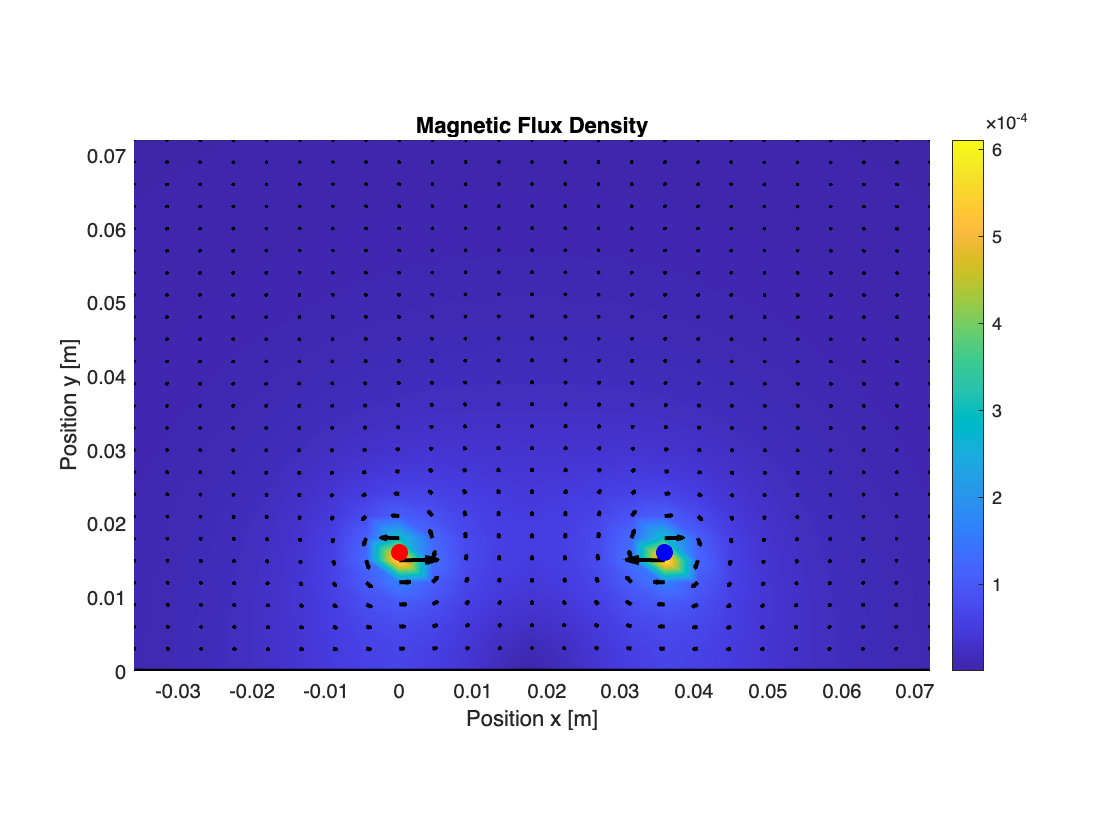


xVtr = linspace(xmin, xmax, 25); 
yVtr = linspace(ymin, ymax, 25);
[xMtx, yMtx] = meshgrid(xVtr, yVtr);

% --- Initialize magnetic field ---
Bx = zeros(size(xMtx));
By = zeros(size(xMtx));

small_offset = 1e-12; % Avoid division with zero

% --- Calculate B-field contributions from each wire and its image ---
% Wire 1 at (0, h1) and its image at (0, -h1)
r1_sq = xMtx.^2 + (yMtx - h1).^2 + small_offset;
r1prime_sq = xMtx.^2 + (yMtx + h1).^2 + small_offset;

Bx = Bx + (mu0/(2*pi)) * I1 * (-(yMtx - h1) ./ r1_sq + (yMtx + h1) ./ r1prime_sq);
By = By + (mu0/(2*pi)) * I1 * (xMtx ./ r1_sq - xMtx ./ r1prime_sq);

% Wire 2 at (w, h2) and its image at (w, -h2)
r2_sq = (xMtx - w).^2 + (yMtx - h2).^2 + small_offset;
r2prime_sq = (xMtx - w).^2 + (yMtx + h2).^2 + small_offset;

Bx = Bx + (mu0/(2*pi)) * I2 * (-(yMtx - h2) ./ r2_sq + (yMtx + h2) ./ r2prime_sq);
By = By + (mu0/(2*pi)) * I2 * ((xMtx - w) ./ r2_sq - (xMtx - w) ./ r2prime_sq);

% --- Magnitude for color map ---
B_magnitude = sqrt(Bx.^2 + By.^2);

% --- Plotting ---
figure;
pcolor(xMtx, yMtx, B_magnitude);
shading interp;
hold on;

% Quiver plot for vector field
quiver(xMtx, yMtx, Bx, By, 1, 'k', 'linewidth', 2)

% Plot wire positions
plot(0, h1, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % Wire 1
plot(w, h2, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); % Wire 2

% Plot ground plane
plot([xmin xmax], [0 0], 'k-', 'LineWidth', 2);

% Add colorbar and labels
colorbar;
title('Magnetic Flux Density');
xlabel('Position x [m]');
ylabel('Position y [m]');
axis equal;
axis([xmin xmax ymin ymax]);

hold off;

3.3.3 (b)

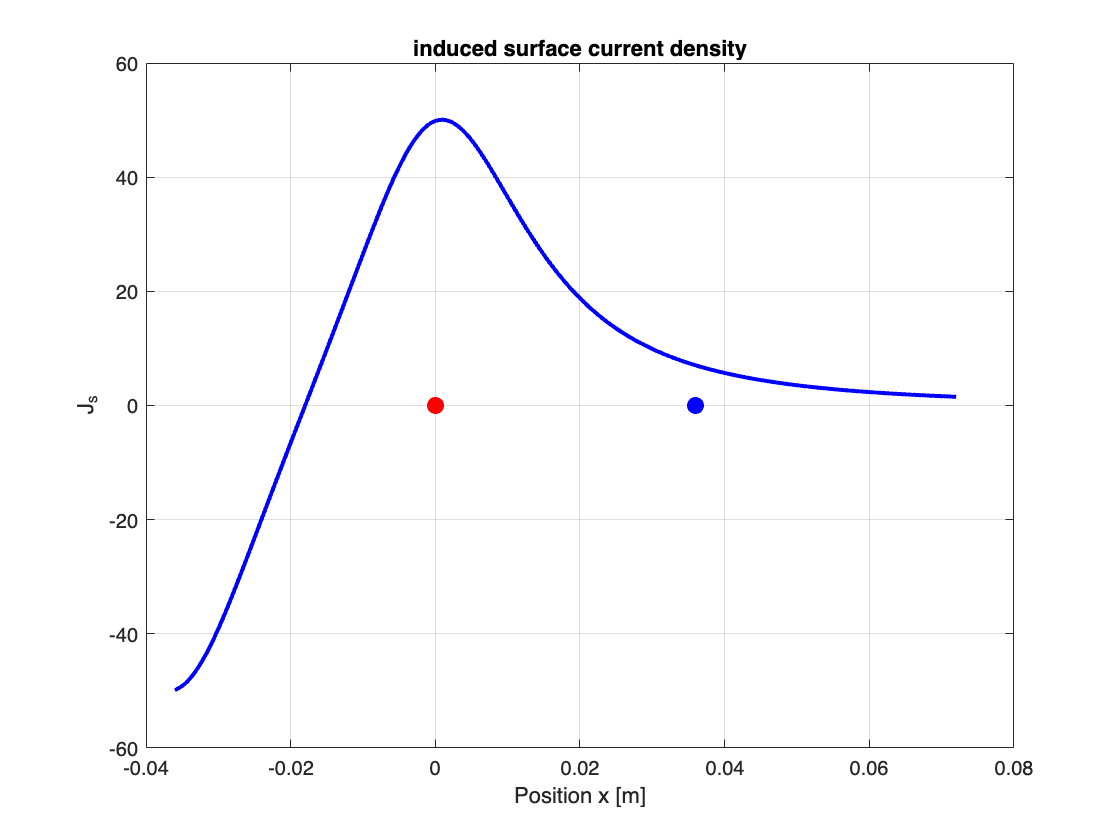

x_plot = linspace(-w, 2*w, 500); 

J_s = (h / pi) * ((I1 ./ (x_plot.^2 + h^2) + (I2 ./ ((x_plot + w).^2 + h^2))));

figure(); 

plot(x_plot, J_s, 'b-', 'LineWidth', 2);
hold on; 

plot(0, 0, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); 
plot(w, 0, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b'); 

title('induced surface current density');
xlabel('Position x [m]');
ylabel('J_s');
grid on; 

hold off;

3.3.4 (a)

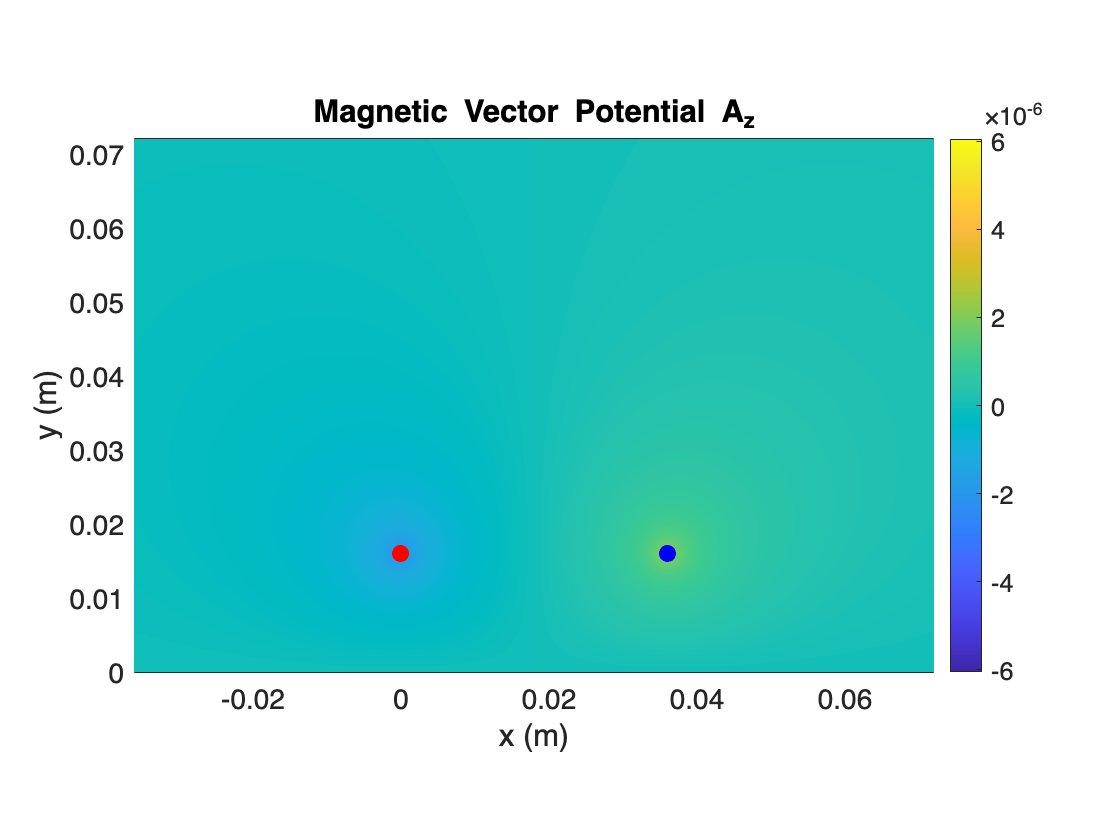

numX = 1000; 
numY = 1000; 
xVtr = linspace(xmin, xmax, numX);
yVtr = linspace(ymin, ymax, numY);
[xMtx, yMtx] = meshgrid(xVtr, yVtr);

% Wire 1 and its image
r1_sq = xMtx.^2 + (yMtx - h1).^2;
r1_img_sq = xMtx.^2 + (yMtx + h1).^2;
% Wire 2 and its image
r2_sq = (xMtx - w).^2 + (yMtx - h2).^2;
r2_img_sq = (xMtx - w).^2 + (yMtx + h2).^2;

small_offset = 1e-12; 
r1_sq = r1_sq + small_offset;
r2_sq = r2_sq + small_offset;

Az = (-mu0/(2*pi)) * I1 * log(sqrt(r1_img_sq)./sqrt(r1_sq)) + ...
     (-mu0/(2*pi)) * I2 * log(sqrt(r2_img_sq)./sqrt(r2_sq));

% Plot
figure(1), clf; 
pcolor(xMtx, yMtx, Az); 
hold on; 

plot(0, h1, 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8); % Wire 1 location
plot(w, h2, 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 8); % Wire 2 location

shading interp; 
colorbar; 
axis equal;
axis([xmin xmax ymin ymax]); 

xlabel('x (m)');
ylabel('y (m)');
title(['Magnetic Vector Potential A_z']);
set(gca, 'fontsize', 14); 

hold off;

3.3.4 (e)

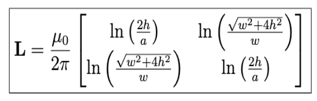

% Matrix elements
L11 = (mu0/(2*pi)) * log(2*h/a);
L12 = (mu0/(2*pi)) * log(sqrt(w^2 + 4*h^2)/w);
L21 = L12; 
L22 = L11; 

% Display the inductance matrix
L = [L11, L12; L21, L22]

L = 1.0e-06 *

    0.6567    0.0582
    0.0582    0.6567
